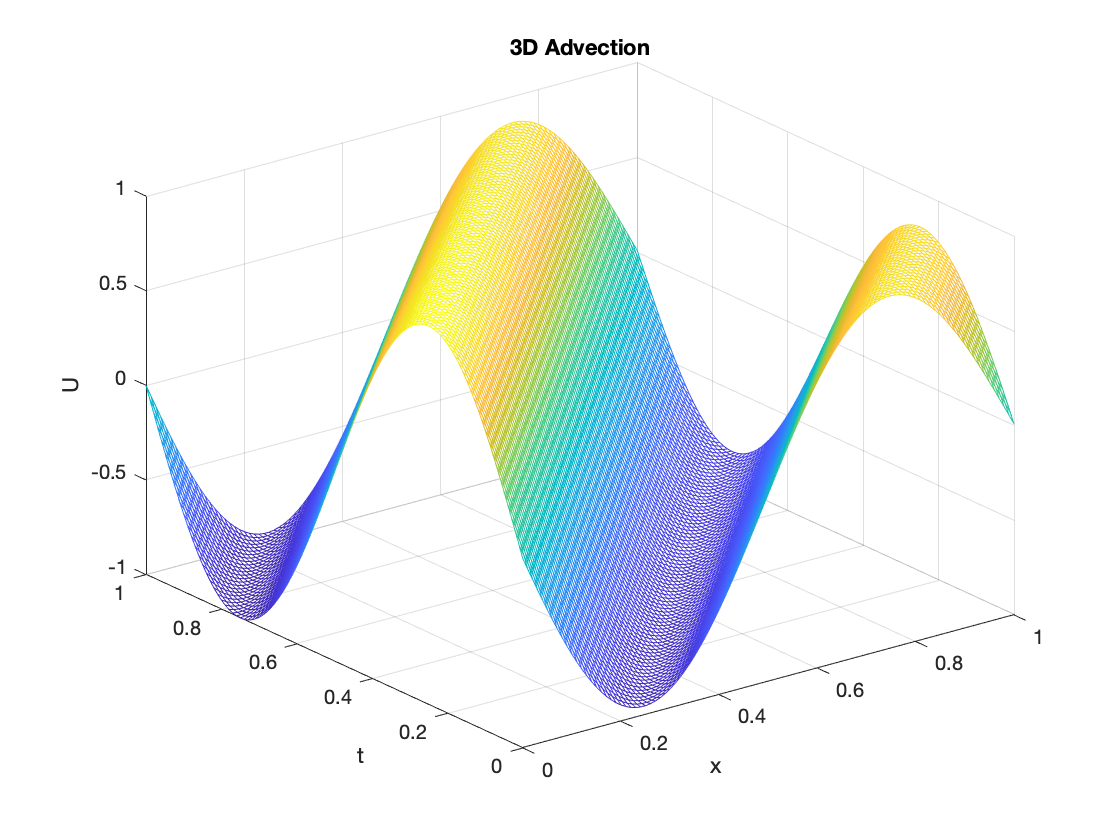

% Using Euler Backwards
T = 1;
dx = 0.01;
xspan = 0:dx:1;
m = length(xspan)-1;
% suppose we have 100 time steps
n = 100;
dt = T/n;
tspan = 0:dt:T;
u0 = @(x) sin(2*pi.*x);
U = zeros(m+1,n+1);
U(:,1) = u0(xspan); % initial condition, t = 0
A = diag(zeros(m,1))+diag(-1*ones(m-1,1),1)+diag(ones(m-1,1),-1);
A(m,1) = -1;
A(1,m) = 1;
A = dt/(2*dx)*A;
I = eye(m);
for i = 1:n
    U(1:m,i+1) = (I-A)\U(1:m,i);
    U(m+1,i+1) = U(1,i+1);
end
% Generate a 3D graph
figure(1);
mesh(xspan,tspan,U(:,:))
xlabel('x')
ylabel('t')
zlabel('U')
title("3D Advection")

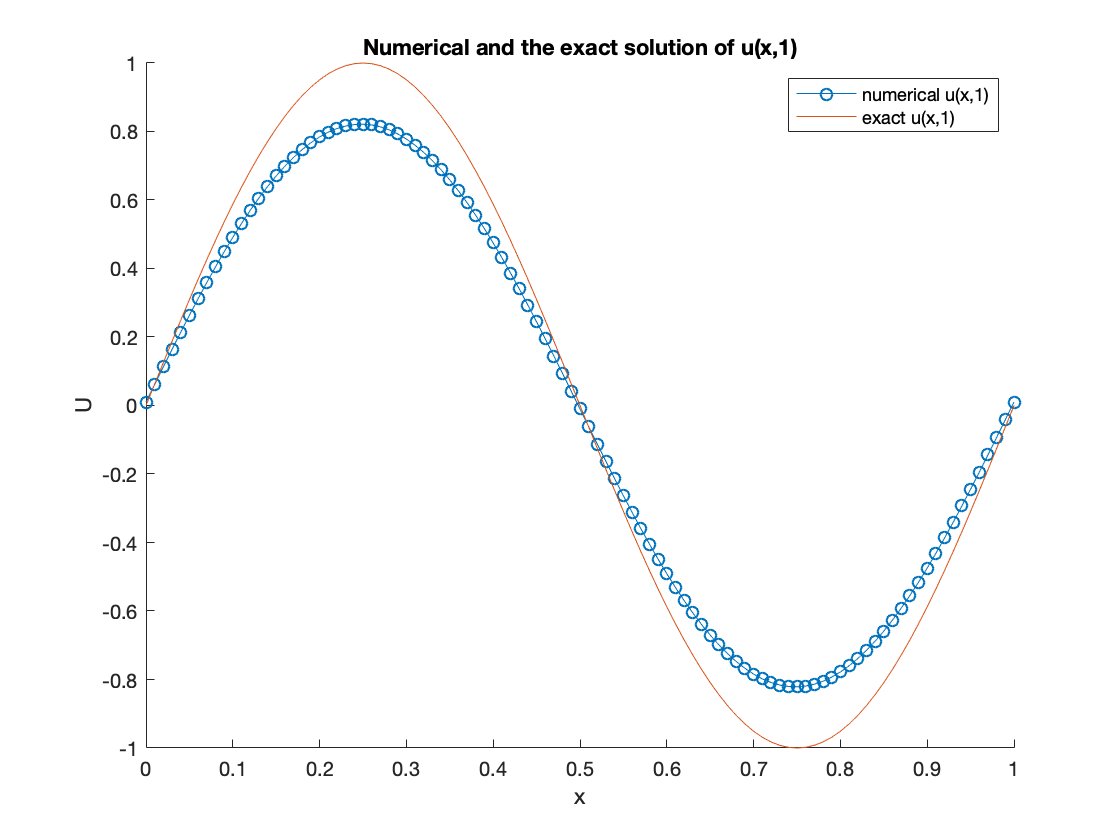

% Graph u(x,1) on a plane
figure(2);
hold off;
hold on;
plot(xspan,U(:,end),'-o')
plot(xspan, u0(xspan-T)) % Exact solution u0(x-T)
legend('numerical u(x,1)','exact u(x,1)')
title("Numerical and the exact solution of u(x,1)")
xlabel('x')
ylabel('U')
hold off;